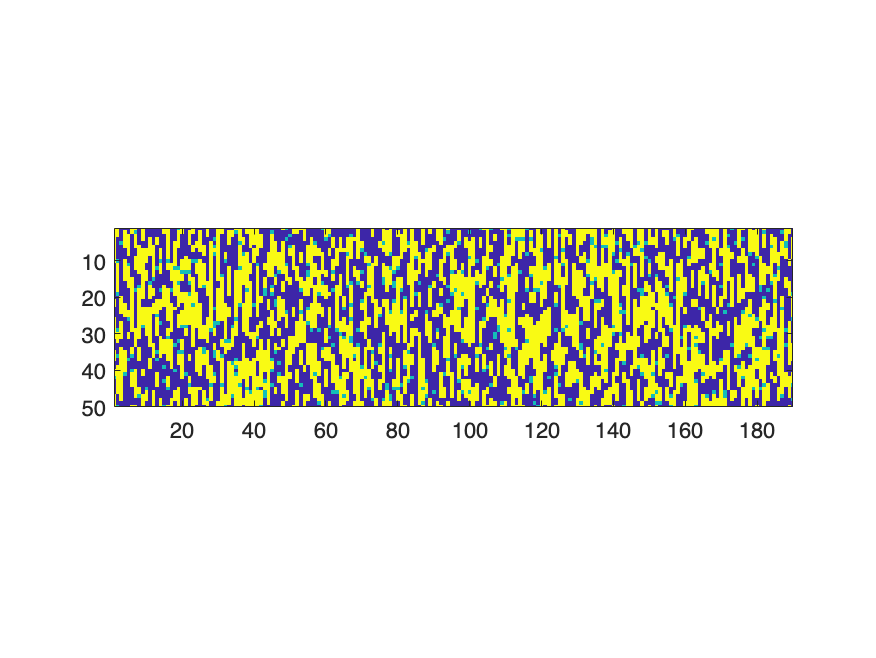

%begin of the main function
clear variables
%define the constant
e = 1.602e-19;
k = 1.381e-23;
B = 0.265;
%setup the size for matrix
row = 50;
col = 190;
%denote 1 as spin +1
map = (randi(2,row,col));
[x,y] = find(map==2);
%let the element 2 become spin -1
for i=1:length(x)
    map(x(i),y(i)) = -1;
end
%dilution
sigma = zeros(row,col);
for i = 1:row
    for j = 1:col
        sigma(i,j) = sigh(i,j);
        %%%dilution the spin
        if sigma(i,j) == 0
            map(i,j) = 0;
        end
    end
end
%create the imgae
figure Name 1
imh = imagesc(cat(2,map));
pbaspect([190 50 1]);
xlim([1 190]);
ylim([1 50]);
%%%%%%%%%
%%%%%%%%%
%d is the coupling constant
d = 0.5;
%T is the tempurature
T = 0.01;
beta = 1/(k*T);
%times for loops
step = 5000;
%setup the waitbar
h = waitbar(0,'please wait');
%generate the random integer to get the position
nt = 10;
im = randi([1 50],nt,step);
jm = randi([1 190],nt,step);
%spinup = ones(1,step/1000);
spinup(1,1) = length(x);
k = 2;
for nout = 1:nt
    for n = 1:step
        %define the position
        i = im(nout,n);
        j = jm(nout,n);
        if sigma(i,j) ~= 0
            %calculate the Energy
            En = Energy(i, j, map, B, d, sigma);
            dE = 2 * En;
            %Inverse the spin
            %map(i,j) = -map(i,j);
            %calculate the new Energy after inverse the spin
            %En1 = Energy(i, j, map, B, d, sigma)
            %loop for the probability and the spin
            if dE < 0
                map(i,j) = -map(i,j);
            elseif dE > 0
                %calculate the probability
                P = double(exp(-1*abs(dE)*beta));
                xr = rand(1,'double');
                
                if xr < P
                    %change to origin spin if x<P
                    map(i,j) = -map(i,j);
                    
                %else
                    %otherwise the probability equals to 1
                    %i,j
                end
            end
            %update the image
            set(imh, 'cdata', cat(2,map))
            if mod(n,1000)==0
                str = ['Total ',num2str(step*nt),' steps in progress...',num2str(n/step*100/nt+((nout-1)/nt)*100),'%'];
                waitbar(n/step/nt+((nout-1)/nt),h,str);
                drawnow
                [x1,y1]=find(map==1);
                spinup(k) = length(x1);
                %if k>4 && (spinup(k-3)+spinup(k-2)+spinup(k-1)+spinup(k))<= 3.995*spinup(k-3)
                %    break
                %end
                k = k+1;
            end
        else
        end
    end
end

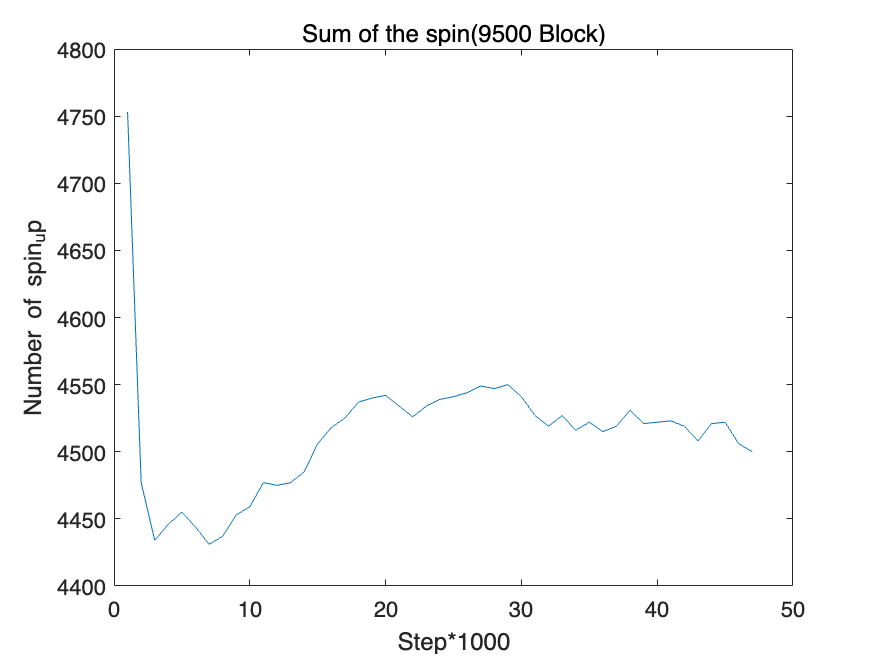

%%%plot the spin
figure Name 2
plot(spinup)
title('Sum of the spin(9500 Block)')
xlabel('Step*1000')
ylabel('Number of spin_up')

delete(h);
